# Example 4: Using Custom Functions to create advanced/graded  TPMS

## 4.1 Defining a standard unit cell parametrically

Similar to shown in example 1, the parameters for the TPMS should be defined. 

clear variables;
TYPE = "surface"; % Types: "network","surface","single", "double", "lattice"
EQUATION = 'Gyroid'; % Which equation to use by default
V1 = 0.5; % Geometry Parameter 1
V2 = 0; % Geometry Parameter 2
VOXSIZE = 1.0; % Resolution - (Size of a voxel edge)
L = 30; % Unit cell size in mm
R = [0 0 0]; % Euler rotation defined as [Rx Ry Rz] in degrees
B = [0 0 0]; % Phase shift/translation [Bx By Bz] in mm
N = [2 2 2]; % Number of unit cells in X,Y,Z
VOLUME = bulkSize('box',L.*N); % Box centered at origin with [lx, ly, lz]

% Use inputs to create the transform object
if verLessThan('matlab', '9.13') % Compatability for older versions of matlab
    TFORM = affine3d([L 0 0 B(1); 0 L 0 B(2); 0 0 L B(3); 0 0 0 1]'); % Definate an affine3d transform here using size and phase shift
else
    TFORM = simtform3d(L,R,B); % Other types of transforms can be defined - this example uses a similarity transform
end

## 4.2 Create a Gradient Density TPMS

To create a graded density TPMS V1 may be input as a array. These values will be linearly interpolated across the design volume.

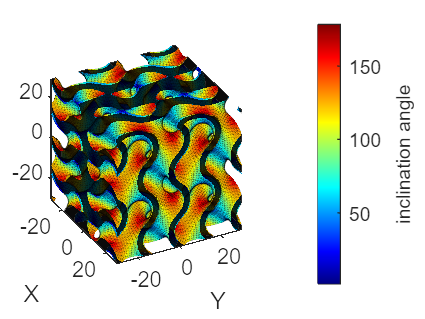

V1a = [0.3 0.8 0.3]; % Define the gradient with a vector.
myCell = UnitCell(TYPE,EQUATION,V1a,V2,VOXSIZE,TFORM,VOLUME); % Initialise
myCell = myCell.compute(); % Compute
myCell.plot("SurfMesh","inclination angle"); % Plot the result

If the equation selected uses V2, this may also be graded. In this example of a surface gyroid V2 represents the isovalue bias

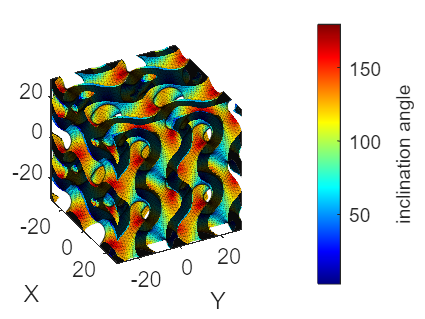

V2b = [0 0.8 0]; % Define the gradient with a vector.
myCell = UnitCell(TYPE,EQUATION,V1,V2b,VOXSIZE,TFORM,VOLUME); % Initialise
myCell = myCell.compute(); % Compute
myCell.plot("SurfMesh","inclination angle"); % Plot the result

A 2D or 3D array may also be used, (this will again be stretched over the bounding box of the design volume)

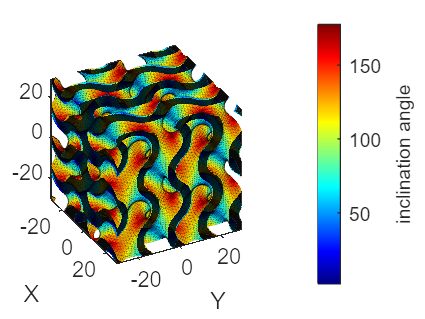

V1c = [0.3 0.8 0.3; 0.5 0.5 0.5]; % Define the volume fraction with an array/volume input
myCell = UnitCell(TYPE,EQUATION,V1c,V2,VOXSIZE,TFORM,VOLUME); % Initialise
myCell = myCell.compute(); % Compute
myCell.plot("SurfMesh","inclination angle"); % Plot the result

## 4.3 Creating gradient cell size

Gradient cell sizes are not currently supported, so a custom equation must be defined to create this effect. Below is an example of creating a custom symbolic function along x and using it to create a linear gradient in cell size.

% Use Symbolic Variables to help setup the equation
syms x y z;
disp(VOLUME.bbox) % Display the bound box size to help decide

   -30   -30   -30
    30    30    30



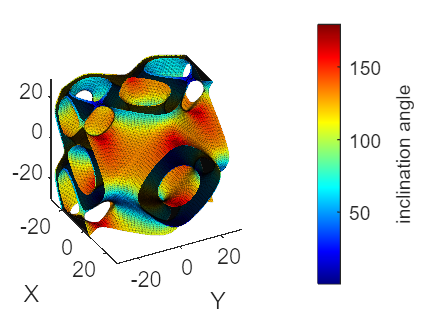

CellSize = 1.5+x/2; % This simple function will map from 1 @ x=-1, to 2 @ x=1;

% EQ 2 is the primitive TPMS
EQ0 = @(x,y,z) cos(2*pi*x)+cos(2*pi*y)+cos(2*pi*z); %Primative Equation as the underlying function
EQRemapped = matlabFunction(EQ0(x./CellSize,y./CellSize,z./CellSize)); % Combine the functions
EQUATION =  func2str(EQRemapped); % Currently conversion to string is required

myCell = UnitCell(TYPE,EQUATION,V1,V2,VOXSIZE,TFORM,VOLUME);% Initialise
myCell = myCell.compute(); % Compute
myCell.plot("SurfMesh","inclination angle"); % Plot the result

## 4.4 Use a weighting function to mix TPMS equations together

To create a custom function, the equations must be defined individually. They can then be mixed using a weighting function (W1). 

Then, as shown before the unit cell is created, computed and plotted. (Note that here no inputs are used for compute, resulting in the default setup, with no curvature or mechanical analysis steps). 

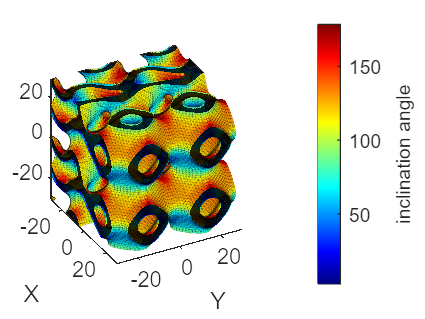

% EQ1 is the Gyroid TPMS
EQ1 = @(x,y,z) (cos(2*pi*x).*sin(2*pi*y)+cos(2*pi*y).*sin(2*pi*z)+cos(2*pi*z).*sin(2*pi*x)); %Gyroid Equation

% EQ 2 is the primitive TPMS
EQ2 = @(x,y,z) (cos(2*pi*x)+cos(2*pi*y)+cos(2*pi*z));

% TPMS Type weighting Function (Must Range from 0 to 1), 
% here a sigmoid function is used with slope parameter 4
W1 = @(x,y,z) 1./(1+exp(4*x)); 

% Symbolics can be defined to create the custom matlabFunction
syms x y z;
EQMIXED = matlabFunction(W1(x,y,z).*EQ1(x,y,z)+(1-W1(x,y,z)).*EQ2(x,y,z)); % Creating the function
EQUATION3 = func2str(EQMIXED); % Combined function converted to string-type 

% Initialise the unit cell: myCell = UnitCell(TYPE,EQUATION,V1,V2,RES,TFORM,VOLUME);
myCell = UnitCell(TYPE,EQUATION3,V1,V2,VOXSIZE,TFORM,VOLUME);
myCell = myCell.compute();
myCell.plot("SurfMesh","inclination angle");